# ECE 101 - Assignment 5 - Plotting & File I/O

Michael Dekoski

4-28-23

% Clear Workspace/Command Window
clear
clc

Start Timer

startTime = clock();

## First Dataset and Plot

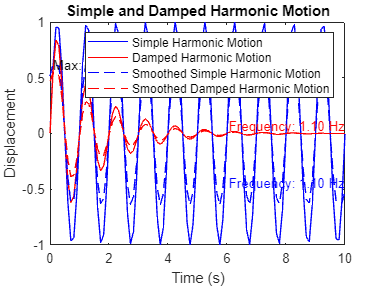

% Create a dummy time vector
time = linspace(0, 10, 100); % Time vector from 0 to 10 seconds with 100 data points

% Parameters for simple harmonic motion
simHarAmp = 1; % Amplitude
simHarFreq = 1; % Frequency in Hz
simHarPhase = 0; % Phase angle in radians

% Parameters for damped harmonic motion
dampHarAmp = 1; % Amplitude
dampHarFreq = 1; % Frequency in Hz
dampHarPhase = 0; % Phase angle in radians
damping_ratio = 0.1; % Damping ratio

% Compute the Y output data for both motions
simHarSol = simHarAmp * sin(2 * pi * simHarFreq * time + simHarPhase);
dampHarSol = dampHarAmp * exp(-damping_ratio * 2 * pi * dampHarFreq * time) .* sin(2 * pi * dampHarFreq * time + dampHarPhase);

% Plot the data
figure;
plot(time, simHarSol, 'b-', 'DisplayName', 'Simple Harmonic Motion');
hold on;
plot(time, dampHarSol, 'r-', 'DisplayName', 'Damped Harmonic Motion');

% Condition the signal (smoothing)
simHarSolSmooth = smoothdata(simHarSol);
dampHarSolSmooth = smoothdata(dampHarSol);

% Plot the conditioned data
plot(time, simHarSolSmooth, 'b--', 'DisplayName', 'Smoothed Simple Harmonic Motion');
plot(time, dampHarSolSmooth, 'r--', 'DisplayName', 'Smoothed Damped Harmonic Motion');
title('Simple and Damped Harmonic Motion');
xlabel('Time (s)');
ylabel('Displacement');
legend('show');

% Label an important point (highest point)
[simHarMax, simHarMaxTime] = max(simHarSolSmooth);
[dampHarMax, dampHarMaxTime] = max(dampHarSolSmooth);
text(time(simHarMaxTime), simHarMax, sprintf('Max: (%.2f, %.2f)', time(simHarMaxTime), simHarMax), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
text(time(dampHarMaxTime), dampHarMax, sprintf('Max: (%.2f, %.2f)', time(dampHarMaxTime), dampHarMax), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

% Make a measurement (frequency)
simHarFFT = abs(fft(simHarSol));
dampHarFFT = abs(fft(dampHarSol));
[~, simHarFFTMaxTime] = max(simHarFFT(1:floor(length(simHarFFT)/2)));
[~, dampHarFFTMaxTime] = max(dampHarFFT(1:floor(length(dampHarFFT)/2)));
simHarSmoothFreq = simHarFFTMaxTime / time(end);
dampHarSmoothFreq = dampHarFFTMaxTime / time(end);

% Put the measurement on the plot
text(time(end), simHarSolSmooth(end), sprintf('Frequency: %.2f Hz', simHarSmoothFreq), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'blue');
text(time(end), dampHarSolSmooth(end), sprintf('Frequency: %.2f Hz', dampHarSmoothFreq), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
hold off


% Save the data set and its conditioned data as a 'readable' file
harmonicData = table(time', simHarSol', dampHarSol', simHarSolSmooth', dampHarSolSmooth', 'VariableNames', {'Time', 'Simple_Harmonic_Motion', 'Damped_Harmonic_Motion', 'Smoothed_Simple_Harmonic_Motion', 'Smoothed_Damped_Harmonic_Motion'});
writetable(harmonicData, 'ECE_101_Assignment5_harmonic_motion_data.csv');

## Second Dataset and Plot

soundCard = audiorecorder;  % This is a ref to a soundcard
disp('Recording start')

Recording start


recordblocking(soundCard, 6);
disp('Recording stop')

Recording stop



soundMag = getaudiodata(soundCard);
soundDeltaT = 1 / 8000;
soundTime = 0:soundDeltaT:6-soundDeltaT;
smoothSound = smoothdata(soundMag, 'movmean', 10);

## Plot for Second Dataset

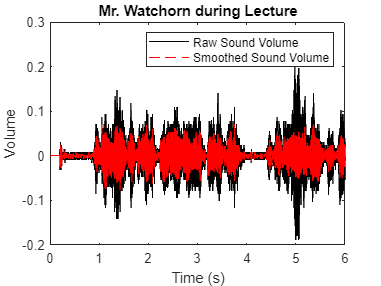

plot(soundTime, soundMag, '-k', soundTime, smoothSound, '--r')

title('Mr. Watchorn during Lecture')
xlabel('Time (s)')
ylabel('Volume')
legend('Raw Sound Volume', 'Smoothed Sound Volume')

[maxSoundMag, maxSoundMagTime] = max(soundMag);
text(soundTime(maxSoundMagTime), maxSoundMag, sprintf('Max: (%.2f, %.2f)', soundTime(maxSoundMagTime), maxSoundMag), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');


% Save the data set and its conditioned data as a 'readable' file
soundData = table(soundTime', soundMag, smoothSound, 'VariableNames', {'Time', 'Sound_Magnitude', 'Smoothed_Sound_Magnitude'});
writetable(soundData, 'ECE_101_Assignment5_sound_data.csv');

## Stop Timer

% End time
stopTime = clock();

Calculate elapsed time

% vector into seconds
startSec = startTime(6) + (startTime(5)*60) + (startTime(4)*3600);
stopSec = stopTime(6) + (stopTime(5)*60) + (stopTime(4)*3600);

dayDiff = stopTime(3) - startTime(3);
dayInSec = dayDiff * 86400;
timeInHours = (stopSec - startSec + dayInSec)/3600;
hour = floor(timeInHours)

hour = 19

hourRem = timeInHours - hour;
timeInMinutes = hourRem * 60;
min = floor(timeInMinutes)

min = 4

minRem = timeInMinutes - min;
sec = minRem * 60

sec = 44.4430